clc;
clear;
audio1=audiorecorder(44100,16,1);
disp("start speaking1");

start speaking1


recordblocking(audio1,5);
disp("end of recording1");

end of recording1


disp("wait");

wait


pause(2);
audio2=audiorecorder(44100,16,1);
disp("start speaking2");

start speaking2


recordblocking(audio2,3);
disp("end of recording2");

end of recording2


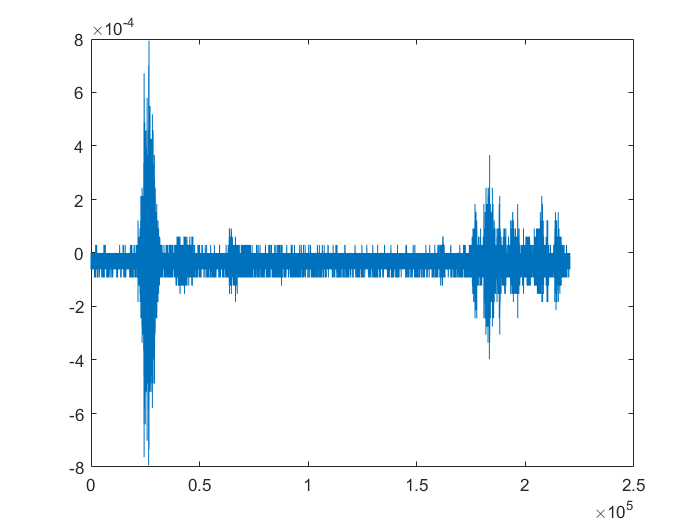

ad1 = getaudiodata(audio1);
ad2 = getaudiodata(audio2);

plot(ad1);

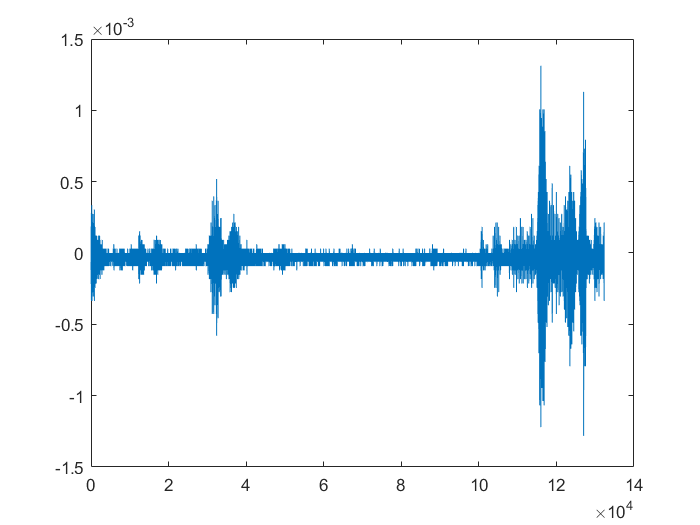

plot(ad2);

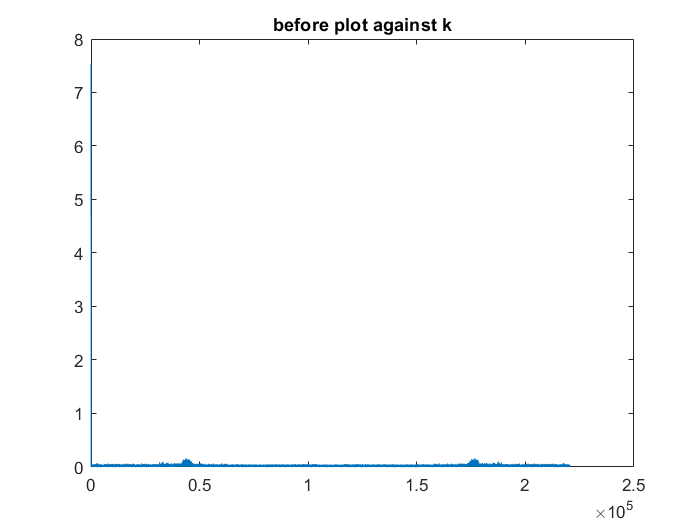

L1= length(ad1);

k=0:L1-1;
ad1_k= fft (ad1,L1);
ad1_f= (0 :L1-1) * (44100/L1);
ad1_shift=(-L1/2:L1/2-1)*(44100/L1);

figure;
plot(k,abs(ad1_k))                             
title ('before plot against k');

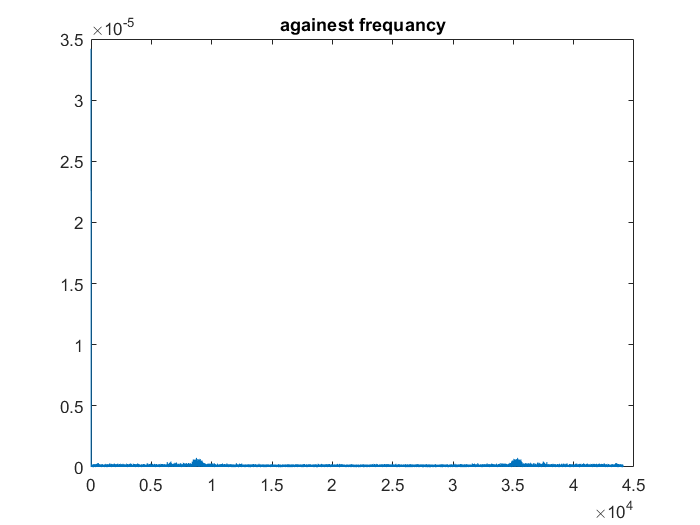

plot(ad1_f,abs(ad1_k)/L1)       
title ('againest frequancy');

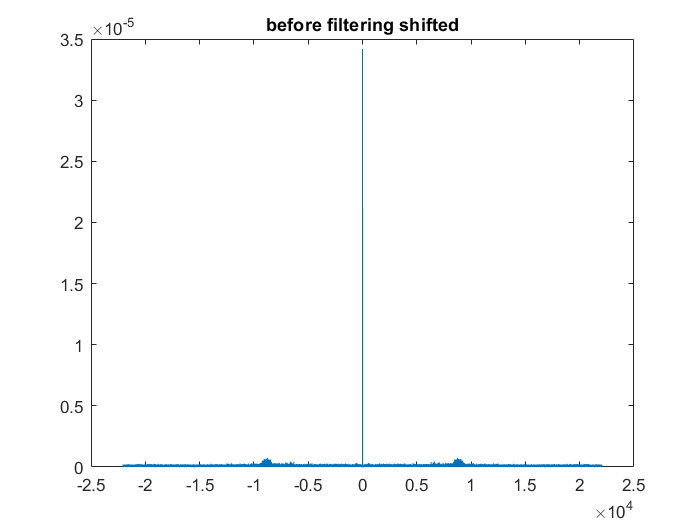

plot(ad1_shift,abs(fftshift(ad1_k))/L1)   
title ('before filtering shifted');

load('LP.mat')

Error using load
Unable to read file 'LP.mat'. No such file or directory.

filtered_audio1 = filter(LP, ad1)
Lf=length(filtered_audio1);
filtered_audio1_f=fft(filtered_audio1,Lf);
figure;
plot(k,abs(filtered_audio1_f)); 
title('filtered againest k');
filterdshift=(- L1/2 : L1/2 - 1)*44100 /L1;
figure;
plot(filterdshift,abs(fftshift(filtered_audio1_f))/ L1);
title ('after filtering shifted');

